## Hour by Hour for Design Month (September)

Conversions:

rad = pi/180;
deg = 180/pi;
W_m2 = 3.1525;
ft2 = 10.764;
in2toft2 = 1/144;

Variables:

ET = 7.5;
delta = 0 * rad;
A = 365*W_m2;
B = 0.177;
C = 0.092;
sunrise = 7;

Other Constants:

noon = 12;
gamma = 45*rad;
sigma = 30*rad;
L = 32*rad;

Hour by Hour:

Ed = 0;
for i = sunrise:noon
    hr = noon - i;
    min = hr*60;
    H = (0.25*(min+ET)) * rad;
    beta = asin(cos(L)*cos(delta)*cos(H) + sin(L)*sin(delta));
    theta = acos(cos(beta)*cos(gamma)*sin(sigma) + sin(beta)*cos(sigma));
    Pdn = A/exp(B/sin(beta));
    Pd = Pdn*cos(theta);
    Pdr = (Pdn*C*2)/(1+cos(sigma));
    Pt = Pd+Pdr;
    Ed = Ed+Pt;
end

Ed for full day:

Ed = Ed*2-Pt;
Ed = Ed/1000

Ed = 7.7650

## Calculation for Number of Solar Panels for Design Month (September)

Eo = ADL for the month of September,

Eo = 62.9; %kWh
nu = 0.1833;

Surface Area of required solar panels to accomodate for design month,

S = Eo / (nu * Ed) * ft2

S = 475.6844

Solar panel dimensions,

l = 65;
b = 39.1;
Area = l * b * in2toft2;

Number of solar panels required,

n = S / Area

n = 26.9520

## Calculation for One Day of Every Month

Table data,

ET = [-11.2; -13.9; -7.5; 1.1; 3.3; -1.4; -6.2; -2.4; 7.5; 15.4; 13.8; 1.6];
delta = [-20; -10.8; 0; 11.6; 20; 23.45; 20.6; 12.3; 0; -10.5; -19.8; -23.45] * rad;
A = [390; 385; 376; 360; 350; 345; 344; 351; 365; 378; 387; 391];
B = [0.142; 0.144; 0.156; 0.180; 0.196; 0.205; 0.207; 0.201; 0.177; 0.160; 0.149; 0.142];
C = [0.058; 0.060; 0.071; 0.097; 0.121; 0.134; 0.136; 0.122; 0.092; 0.073; 0.063; 0.057];
sunrise = [8; 7; 7; 6; 6; 5; 6; 6; 7; 7; 8; 8];
ADL = [22.6; 21.1; 17.7; 23.5; 36.1; 53.6; 66.3; 71.6; 62.9; 36.3; 29.8; 21.1];

Hour by Hour for Each Month:

Ed = zeros(12,1);
for i = 1:12
    for j = sunrise(i):noon
        hr = noon - j;
        min = hr*60;
        H = (0.25*(min+ET(i))) * rad;
        beta = asin(cos(L)*cos(delta(i))*cos(H) + sin(L)*sin(delta(i)));
        theta = acos(cos(beta)*cos(gamma)*sin(sigma) + sin(beta)*cos(sigma));
        Pdn = A(i)*W_m2/exp(B(i)/sin(beta));
        Pd = Pdn*cos(theta);
        Pdr = (Pdn*C(i)*2)/(1+cos(sigma));
        Pt = Pd+Pdr;
        Ed(i) = Ed(i)+Pt;
    end
    Ed(i) = Ed(i)*2-Pt;
    Ed(i) = Ed(i)/1000;
end

Eo calculation

Eo = zeros(12,1);
for i = 1:12
    Eo(i) = nu * (S/ft2) * Ed(i);
end

Plot for ADL and Eo for 12 months,

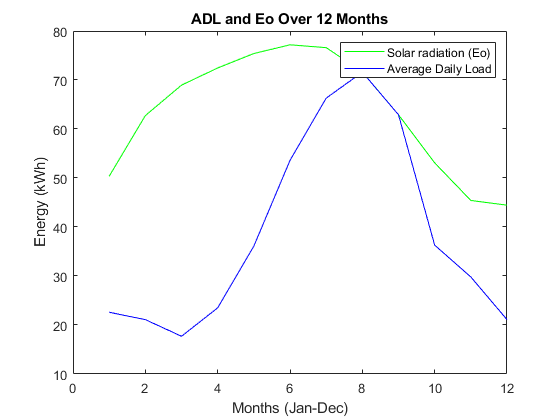

plot(1:12, Eo, 'g', 1:12, ADL, 'b')
title('ADL and Eo Over 12 Months')
xlabel('Months (Jan-Dec)')
ylabel('Energy (kWh)')
legend('Solar radiation', 'Average Daily Load')

Visual Reference for Table with Ed,

Table = [ET delta A B C sunrise ADL Eo]; % for visual reference only